clc;
clear all;

# 1D Hughes Flow Problem (Meeting 4)

There has been a chnage in plan. In this report we are going to solve the 1D Hughe's flow problem, rather then the 2D hughe's flow problem. So given below is theflow of the report.

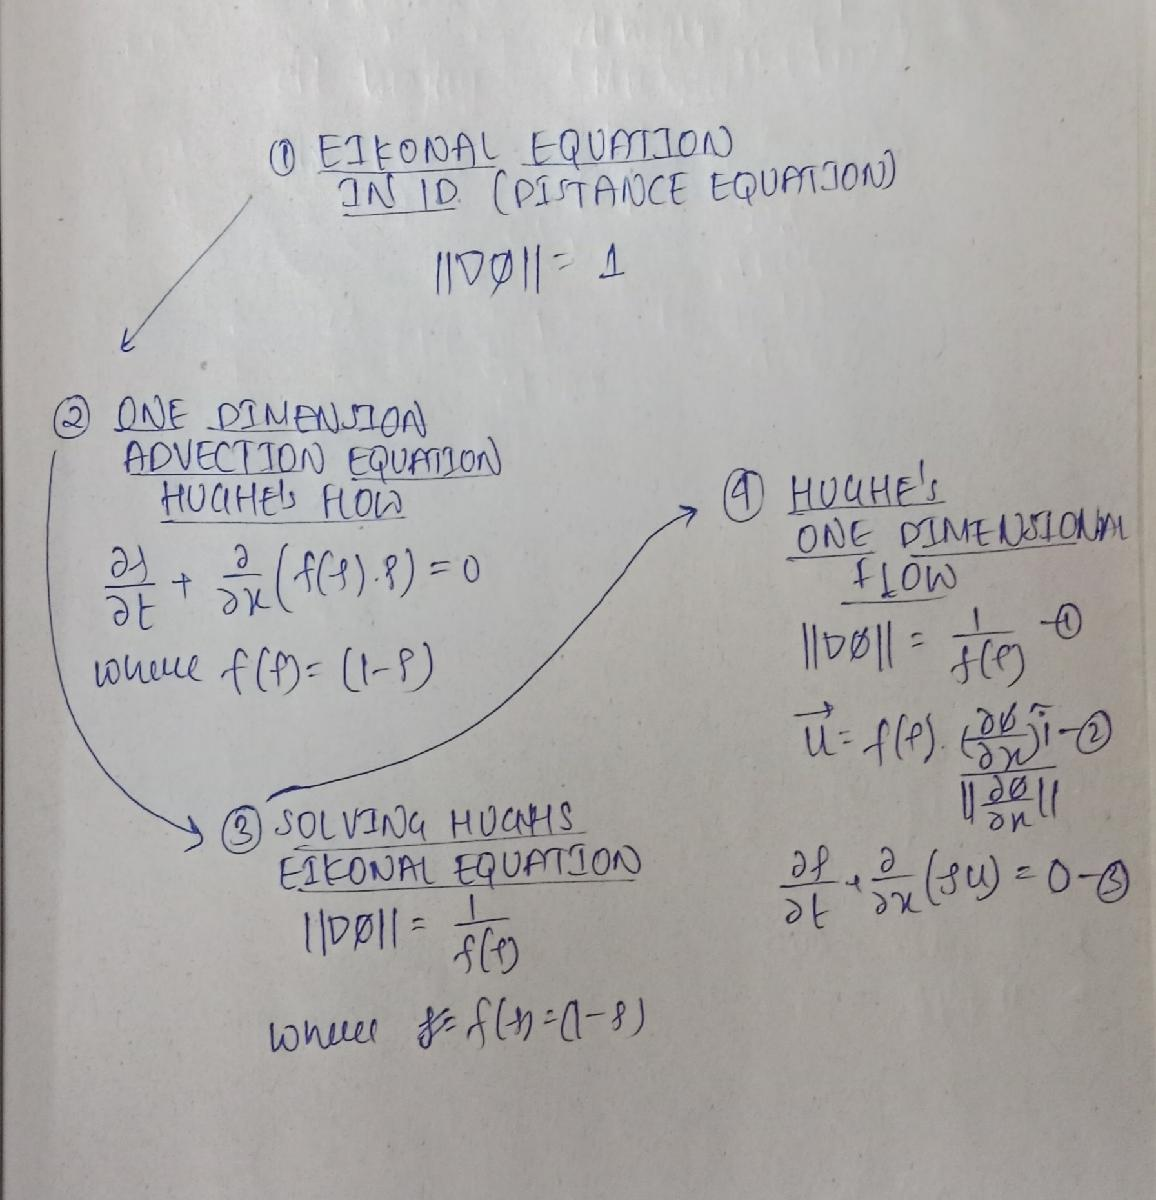

# Eikonal equation in one dimension

In this section I have first tried formulating the eikonal eqaution in one dimension. And tried solving it for a simple problem. So the problem that I have choosen (which is to solve the eikonal equation in one dimension) is called the **Distance function**. And the following resource makes it simple to undertsnad what is distnce function -> [Distance_Function](https://www.danielduffy.org/post/why_do_distance_functions_satisfy_an_eikonal_eqn/why_do_distance_functions_satisfy_an_eikonal_eqn.pdf)

So here is the problem formulation:

I have the doiman to be a oner dimensional line from x = 0 to x = 1. and the value of *phi* is equal to zero, at x = 1. But it normal derivative which is it's partial derivative in x dirction is equal to zero at x = 1. I will be using ghost point approach to implement this boundary condition. So I am dividing the domain into 100 grids points, and i = 1 which will assigned as ghost point, and i = 101 is the Boundary point (Dirichlet condition). And remaining i = 2:101 will be the interior points where the eqaution will be solved.

I am doing this to validate and understand how and does eikonal equaltion work as expected in one dimensional domian. It is easier to understand this equation in one dimension than in two dimension.

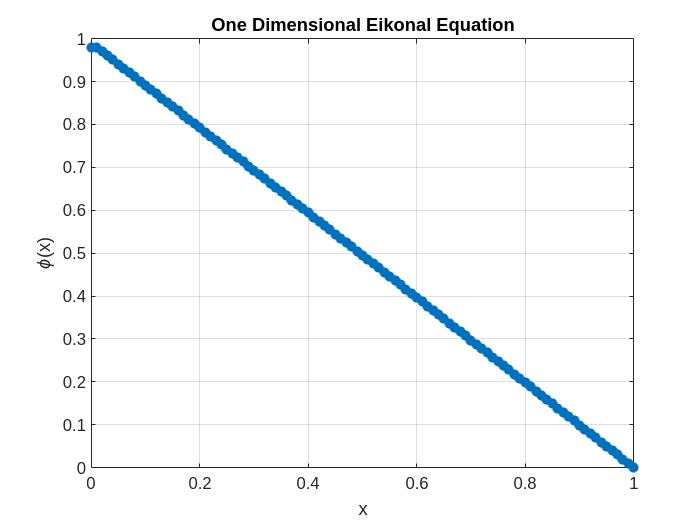

% Defining the domian
Nx= 101;
% Dimension of the domain
L = 1;
% Grid spacing
dx = L/Nx;
% Definging the distance function
phi = inf(1,Nx); % Is is said to define the phi to be infinity in the papers, before sweep.

sweep = 2;

for j = 1:sweep
    % We first update the boundary condition
    phi(Nx) = 0;
    phi(1) = phi(2);
    % Sweep from right to left
    for i = 2:Nx-1
        phi(i) = min(min(phi(i-1),phi(i+1))+dx,phi(i));
    end
    % Sweep from left to right
    for i=Nx-1:-1:2
        phi(i) = min(min(phi(i+1),phi(i-1))+dx,phi(i));
    end
    % Sweep is complete
end
% Now that the values of phi is updated we could visuylaise the solution
X = linspace(0,L,Nx);
plot(X, phi, '*', 'LineWidth', 2);
xlabel('x');
ylabel('\phi(x)');
title('One Dimensional Eikonal Equation');
grid on;

xlim("auto")
ylim("auto")

Now if we just try to understand the result, we got some sensible ones. The results are as follows. Distance function tell me the shortest distnce (displacement) of the point from some reference point which in this case was at x = Nx. 

It can also be understood that **The velocity of pedestrians must be in direction negative to direction of gradient of phi**, and from the above graph, we see that the gradient of phi is always negative whcih means the velocity should be positive everywhere, which is understandable since the exit is at x = 1 (To the right /Positive direction)

# One Dimensional Advection Equation with Greensheild's Definition

In this section I wish to solve **One dimensional advection equation**. And as done before I will be using the **lax wendroff scheme** for solving this advection equation in one dimension. So given below is the stencil of the lax wendroff scheme for one dimension non linear Advection eqaution (1D continuity). 

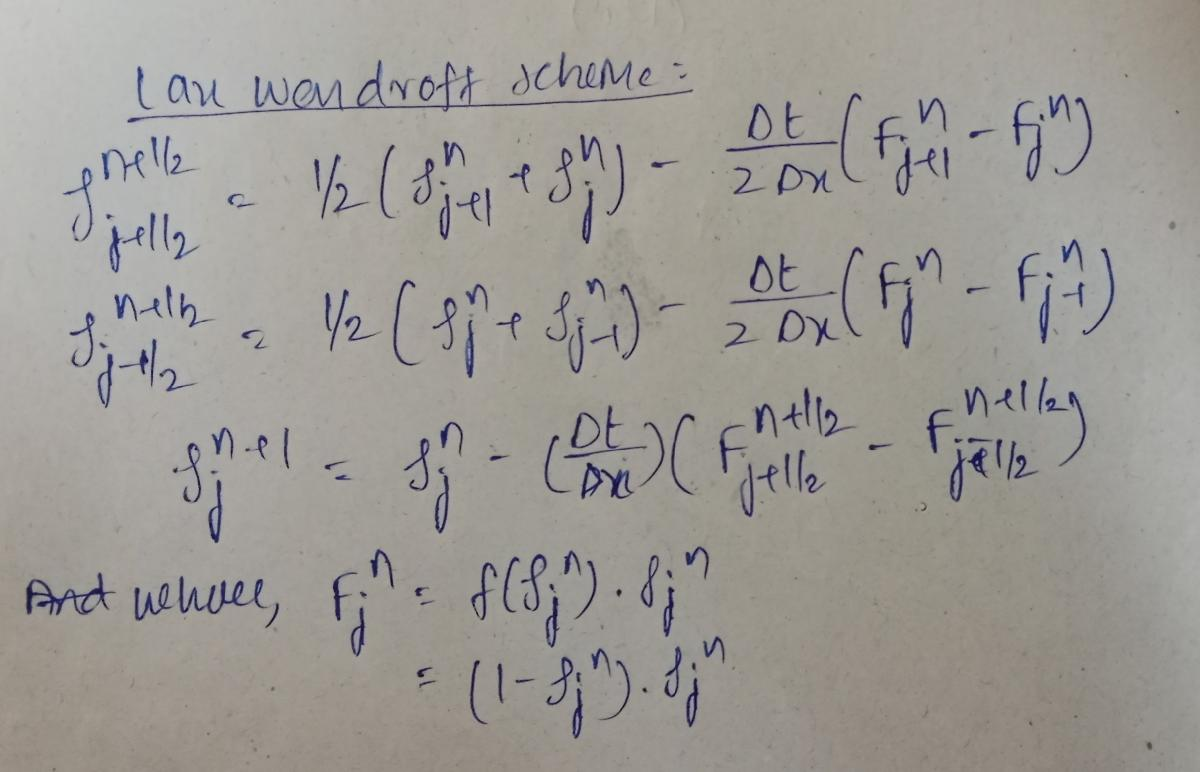

Now lets assume for a moment that the velocity of the advection is in the positve direction only. (this assumption will break when the we solve the hughe's flow becuase in that case the x component of velocity can be in two direction +ve or -ve, and that will depend on the phi values in the domian). Magnitude of velocity which is function of density (which is also why the equation is non linear) is known and hence the value of 'u' could be substitued in the above equation. And that make the eqaution as follows:

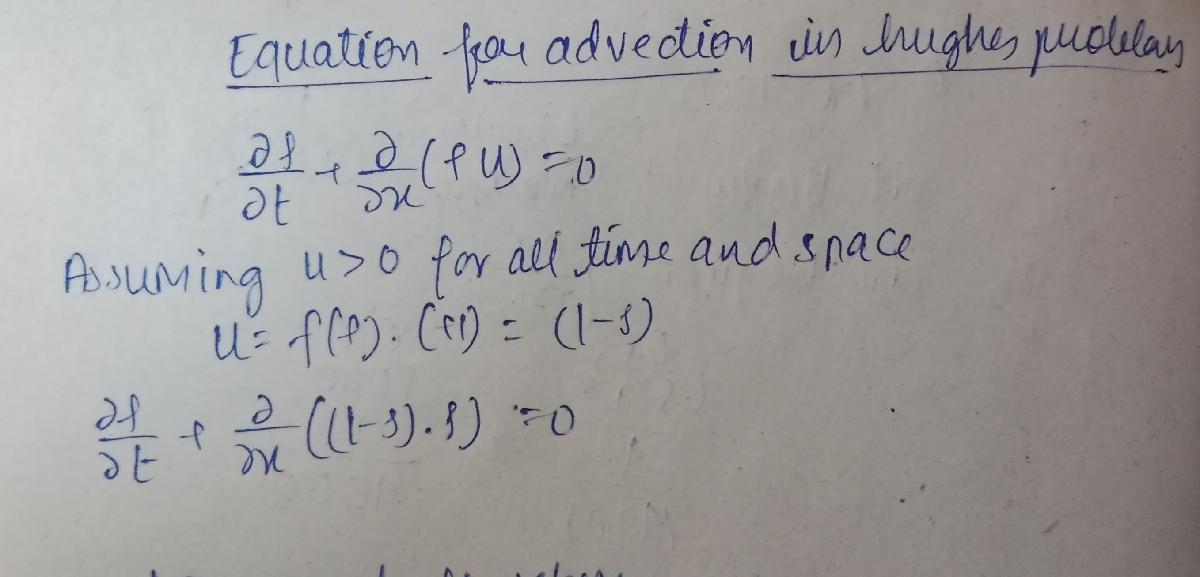

## Problem Formulation

So I have the domian to be a one dimensional line from x = 0 to x = 1. The density at t = 0 is such that it is zero everywhere else and is equal to 1, from x = 0.2 to x = 0.3. Now the advection eqaution is stated as shown below:

The following stencil is used to program the code:

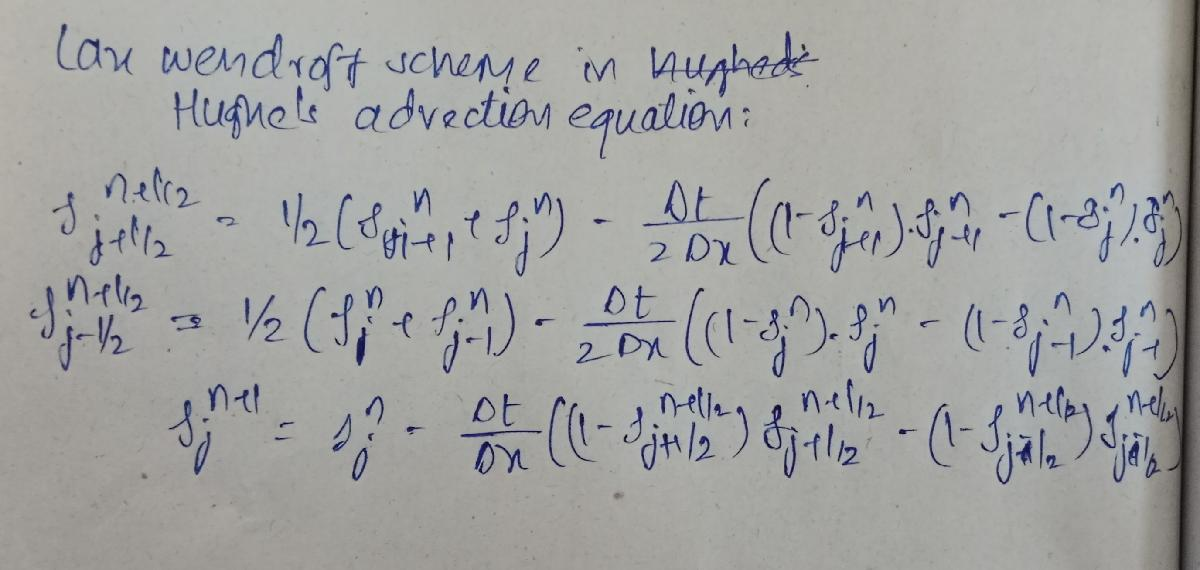

For the boundary conidtion I have enforced outflow condition. And this means the gradient of density is zero at the outflow. And i tried acheving this using ghost poitn approach. Where the boundary point is assigned the same value as it's neighbour.

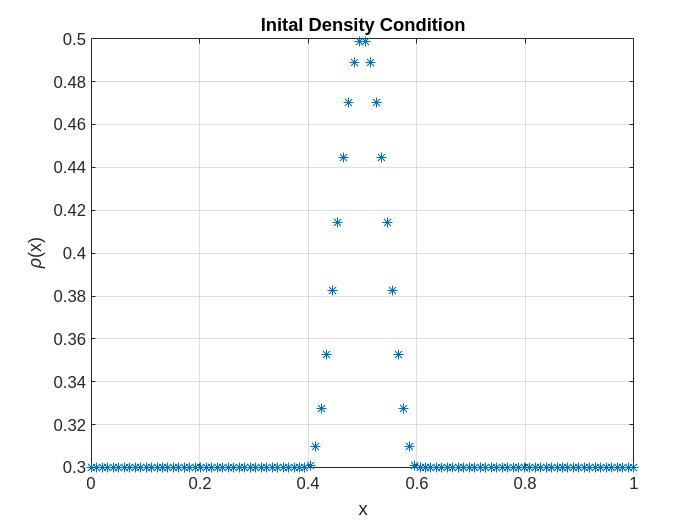

Nx = 100;
L = 1;
x = linspace(0, L, Nx);

rho_disconti = zeros(size(x));
for i = 1:Nx
    if x(i) >= 0.4 && x(i) <= 0.6
        rho_disconti(i) = 0.99;
    end
    % Else, rho remains 0
end

rho_gauss = zeros(size(x));
for i = 1:Nx
    if x(i) >= 0.4 && x(i) <= 0.6
        % Raised cosine bump
        rho_gauss(i) = 0.1 * (1 + cos(pi * ((x(i) - 0.5) / 0.1)))+0.3;
    else rho_gauss(i) = 0.3;
    end
    
end

rho = rho_gauss;
% Plot initial condition
figure;
plot(x, rho,'*');
xlabel('x');
ylabel('\rho(x)');
title("Inital Density Condition");
grid on;


% Time-stepping parameters
total_time = 8;
time_steps = 5000;
dt = total_time / time_steps;
dx = L / Nx;

% Prepare storage for snapshots every 100 steps
time_interval = 100;
rho_final = zeros(Nx, time_steps / time_interval);
snapshot = 0;

% Flux function
fF = @(rho) rho.*(1 - rho);

% -----------------------------
% Lax-Wendroff time loop
% -----------------------------
for t = 1:time_steps
    rho_old = rho;

    for i = 2:Nx-1
        rho_half_right = 0.5*(rho_old(i)+rho_old(i+1)) - (dt/(2*dx))*(fF(rho_old(i+1)) - fF(rho_old(i)));
        rho_half_left  = 0.5*(rho_old(i-1)+rho_old(i)) - (dt/(2*dx))*(fF(rho_old(i)) - fF(rho_old(i-1)));

        F_half_right = rho_half_right.*(1 - rho_half_right);
        F_half_left  = rho_half_left.*(1 - rho_half_left);

        rho(i) = rho_old(i) - (dt/dx)*(F_half_right - F_half_left);
    end
    rho = max(0, min(1, rho));
    % Boundary conditions
    rho(1) = 0; % i assign this dirichlet condition such that there is no inflow of people coming into the domain.

    % Store snapshots every 'time_interval' steps
    if mod(t, time_interval) == 0
        snapshot = snapshot + 1;
        rho_final(:, snapshot) = rho;
        fprintf('Time step = %d / %d\n', t, time_steps);
    end
end

Time step = 100 / 5000
Time step = 200 / 5000
Time step = 300 / 5000
Time step = 400 / 5000
Time step = 500 / 5000
Time step = 600 / 5000
Time step = 700 / 5000
Time step = 800 / 5000
Time step = 900 / 5000
Time step = 1000 / 5000
Time step = 1100 / 5000
Time step = 1200 / 5000
Time step = 1300 / 5000
Time step = 1400 / 5000
Time step = 1500 / 5000
Time step = 1600 / 5000
Time step = 1700 / 5000
Time step = 1800 / 5000
Time step = 1900 / 5000
Time step = 2000 / 5000
Time step = 2100 / 5000
Time step = 2200 / 5000
Time step = 2300 / 5000
Time step = 2400 / 5000
Time step = 2500 / 5000
Time step = 2600 / 5000
Time step = 2700 / 5000
Time step = 2800 / 5000
Time step = 2900 / 5000
Time step = 3000 / 5000
Time step = 3100 / 5000
Time step = 3200 / 5000
Time step = 3300 / 5000
Time step = 3400 / 5000
Time step = 3500 / 5000
Time step = 3600 / 5000
Time step = 3700 / 5000
Time step = 3800 / 5000
Time step = 3900 / 5000
Time step = 4000 / 5000
Time step = 4100 / 5000
Time step = 4200 / 5000
T

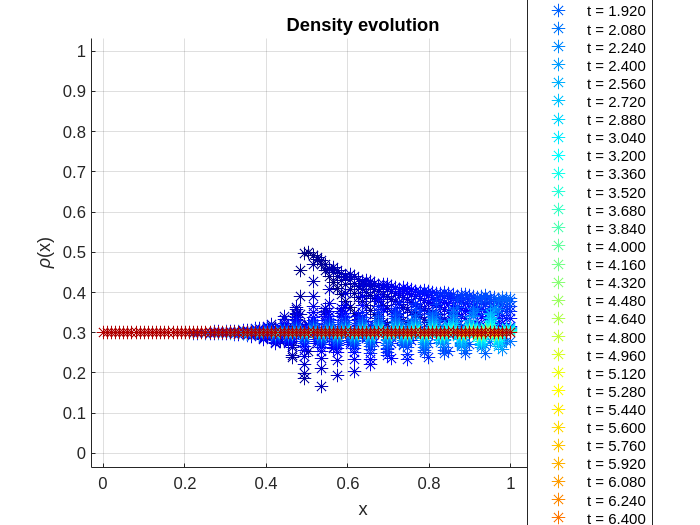

% -----------------------------
% Plot all stored snapshots
% -----------------------------
figure;
hold on;

num_snapshots = size(rho_final, 2);
colors = jet(num_snapshots);
legend_entries = {};

for s = 1:num_snapshots
    plot(x, rho_final(:, s), '*', 'MarkerSize', 8, 'Color', colors(s,:), 'LineStyle', 'none');
    legend_entries{end+1} = sprintf('t = %.3f', s*time_interval*dt);
end

xlabel('x');
ylabel('\rho(x)');
title('Density evolution');
grid on;
legend(legend_entries, 'Location', 'best');
hold off;

legend("Position", [0.92891,0.17175,0.17679,0.74643])

xlim([-0.25 1.36])
ylim([-0.43 0.86])
legend("Position", [0.75462,0.14127,0.17679,0.74643])

xlim([-0.029 1.302])
ylim([-0.035 1.031])

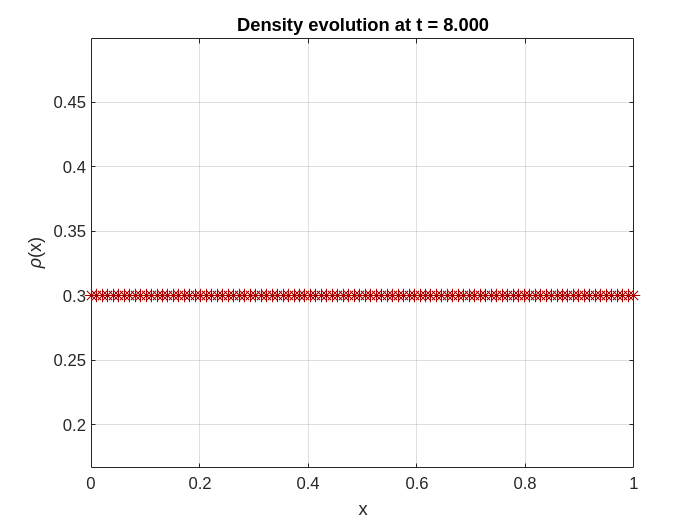

figure;
for s = 1:num_snapshots
    clf; % Clear current figure for fresh plot
    plot(x, rho_final(:, s), '*', 'MarkerSize', 8, 'Color', colors(s,:), 'LineStyle', 'none');
    xlabel('x');
    ylabel('\rho(x)');
    title(sprintf('Density evolution at t = %.3f', s*time_interval*dt));
    xlim([min(x), max(x)]);
    ylim([min(rho_final(:)), max(rho_final(:))]);
    grid on;
    pause(0.5); % adjust pause duration for frame speed
    drawnow;
end

Now we have understood the density variation with the non linear density eqaution we have in hand. 

# Solving Hughe's Eikonal Equation in One Dimension

In this section, I have tried solving the Eikonal Equation equation in One dimension. So the domain is as follows. There is a density concentration at $x = 0.4$ to $x =0.6$, and then the corresponding value of $f(\rho)$ is calculated using the greensheild's formula, $f(\rho) = 1 - \rho$. And then the fast sweep method is applied on the governing equation which is:

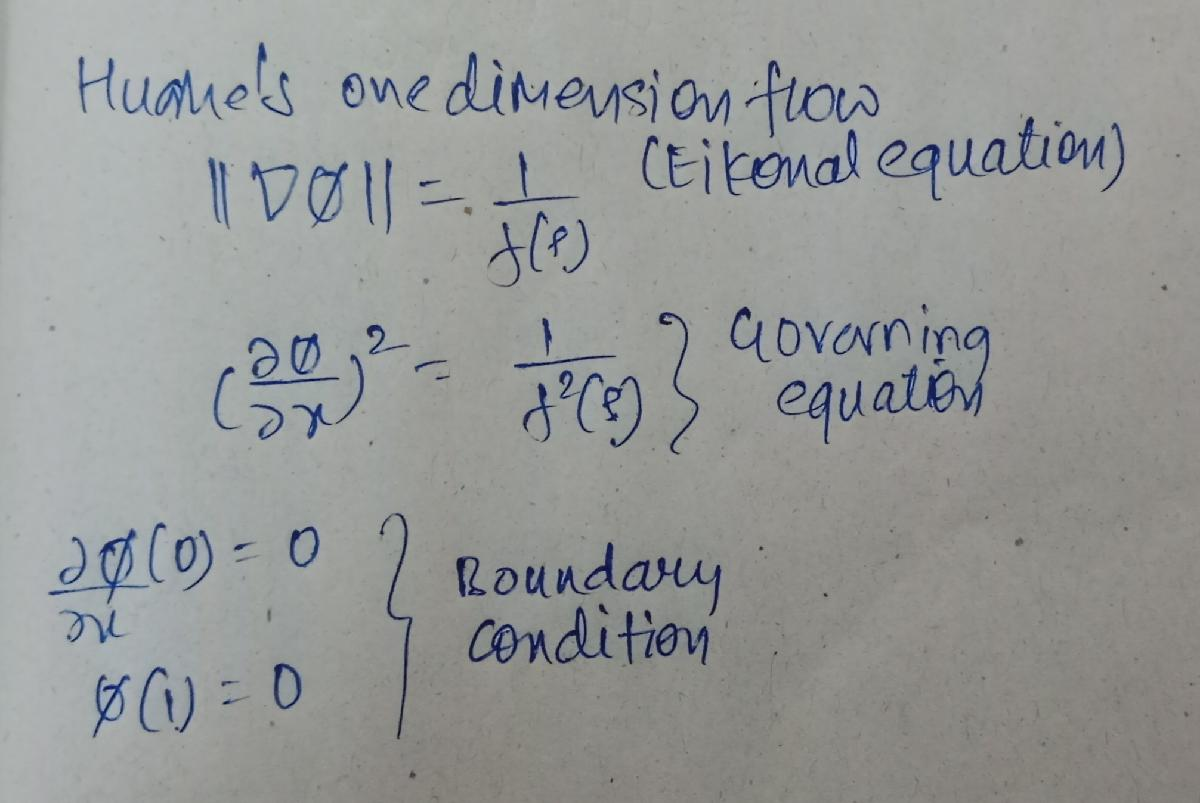

And this could also make the 

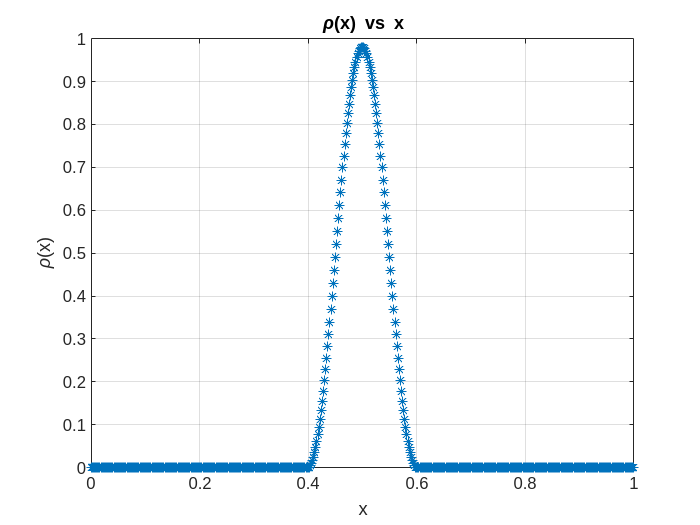

% Defining the domian
Nx= 501;
% Dimension of the domain
L = 1;
% Grid spacing
dx = L/Nx;
% Phi
phi = inf(1,Nx); % Is is said to define the phi to be infinity in the papers, before sweep.

x = linspace(0, L, Nx);
rho_gauss = zeros(size(x));
for i = 1:Nx
    if x(i) >= 0.4 && x(i) <= 0.6
        % Raised cosine bump
        rho_gauss(i) = 0.1 * (1 + cos(pi * ((x(i) - 0.5) / 0.1))) + 0.3;
    else rho_gauss(i) = 0.3
    end
    % Else, rho remains 0
end
% f = 1 - rho
f = ones(size(x));
for i = 1:Nx
    f(i) = 1 - rho_gauss(i);
    % Else, rho remains 1
end
% Plot initial condition
figure;
plot(x, rho_gauss,'*');
xlabel('x');
ylabel('\rho(x)');
title("\rho(x) vs x");
grid on;

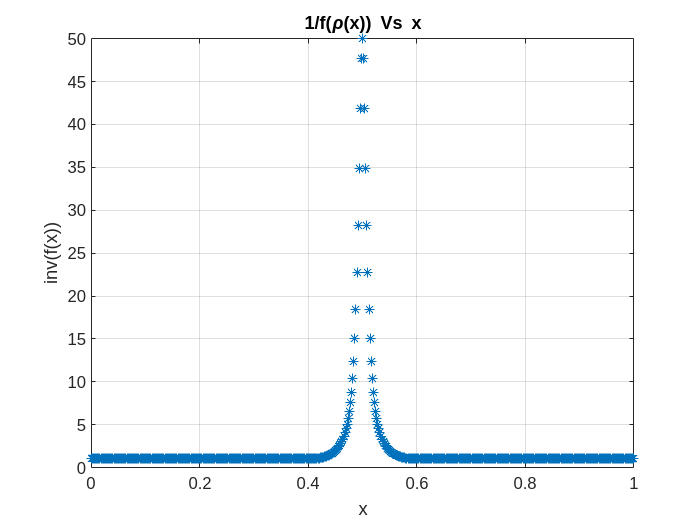

% Plot initial condition
figure;
plot(x, 1./f,'*');
xlabel('x');
ylabel('inv(f(x))');
title("1/f(\rho(x)) Vs x");
grid on;

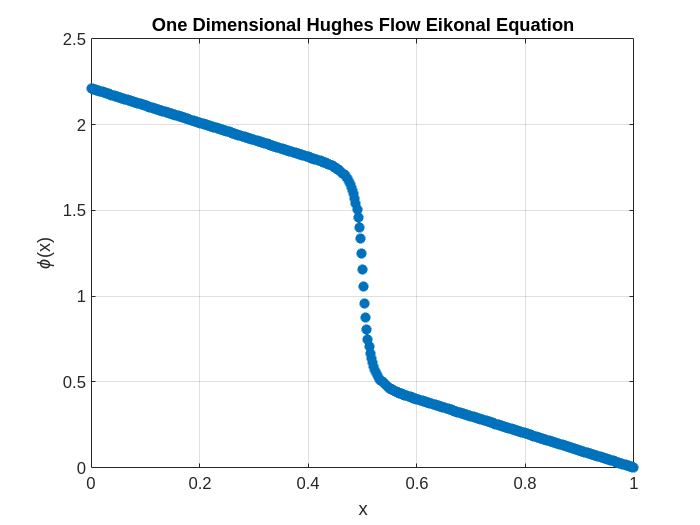

sweep = 4;

for j = 1:sweep
    % We first update the boundary condition
    phi(Nx) = 0;
    phi(1) = phi(2);
    % Sweep from right to left
    for i = 2:Nx-1
        phi(i) = min(min(phi(i-1),phi(i+1))+dx*(1/f(i)),phi(i));
    end
    % Sweep from left to right
    for i=Nx-1:-1:2
        phi(i) = min(min(phi(i+1),phi(i-1))+dx*(1/f(i)),phi(i));
    end
    % Sweep is complete
end
% Now that the values of phi is updated we could visuylaise the solution
X = linspace(0,L,Nx);
plot(X, phi, '*', 'LineWidth', 2);
xlabel('x');
ylabel('\phi(x)');
title('One Dimensional Hughes Flow Eikonal Equation');
grid on;

xlim("auto")
ylim("auto")

# Hughe's Flow in one dimension

Now that I have gained some understanding about eikonal equation in hughe's flow, and have also understood how the non linear hyperbolic equaiton is used for advection, we could finally solve the equations both at once, to solve the hguhe's flow in one dimension.

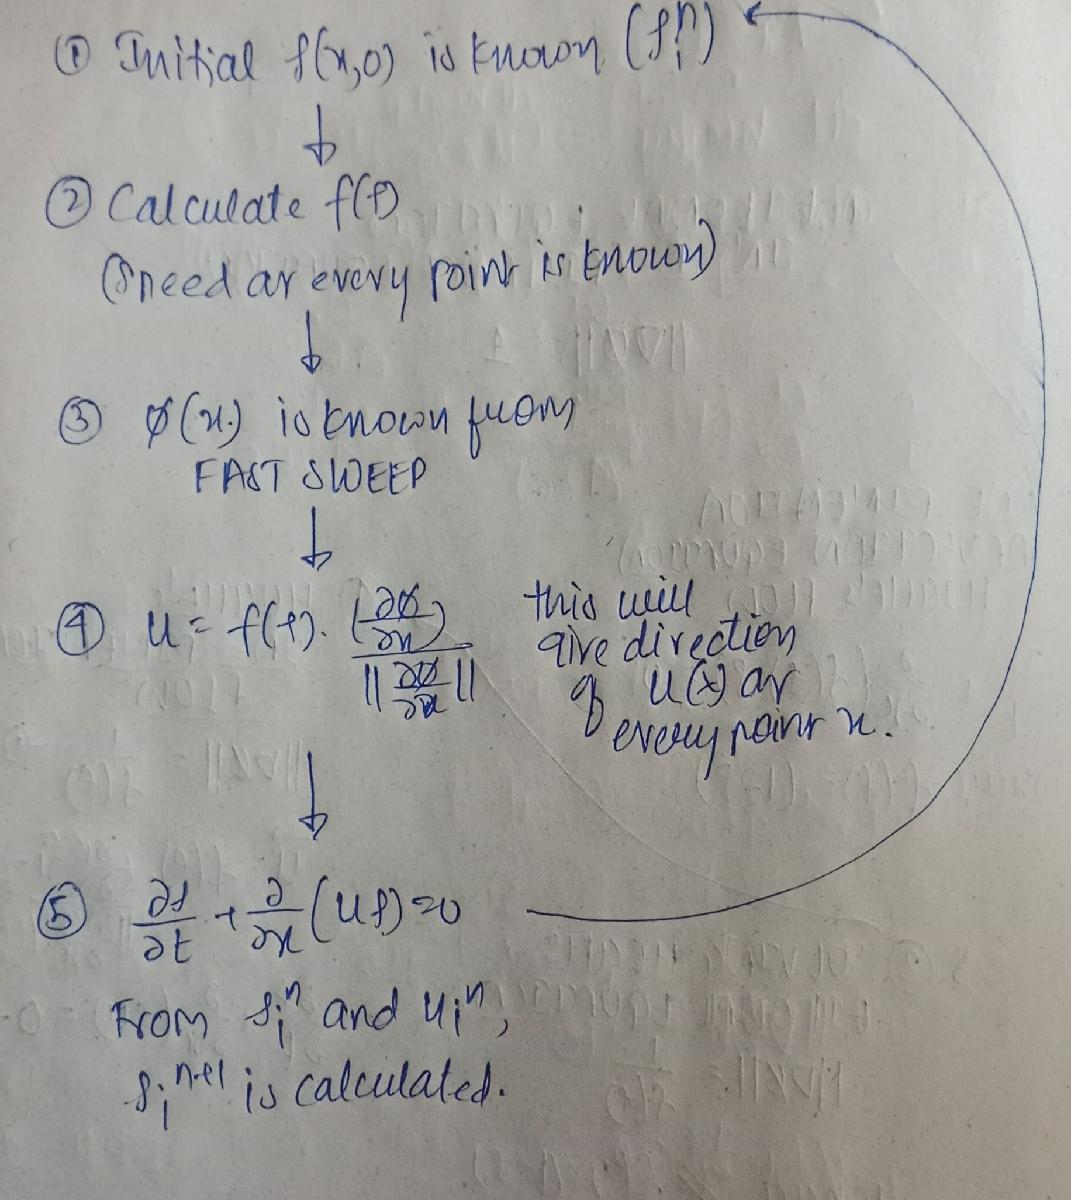

So here I have the Domian as x = 0 to x = 1. And the density is such that it is eqaul to zero everywhere, and it follows gaussian distribution from x = 0.4 to x = 0.6. The value of phi is zero x = 1, and the its gradient at x=1 is zero. Also the gradient of density is zero at x = 0 and x = 1. And now we solve the eikonal equation.

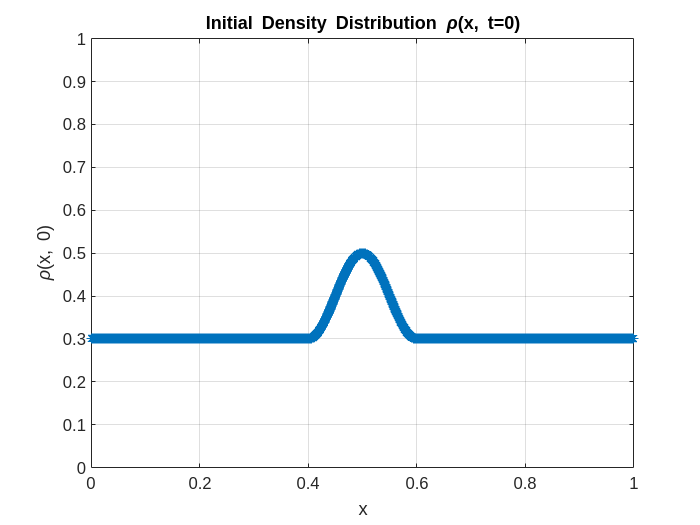

L_hughes = 1;                              % Dimension of domian in X
N_hughes = 4000;                            % No of grid points
dx_hughes = L_hughes/N_hughes;             % Space Interval
X_hughes = linspace(0,L_hughes,N_hughes);  % Preparing the grid point for plot

% Initialising the density
rho_hughes = zeros(1,N_hughes);
f_hughes = zeros(1,N_hughes);
for i = 1:N_hughes
    if X_hughes(i)>=0.4 && X_hughes(i)<=0.6
        rho_hughes(i) = 0.1 * (1 + cos(pi * ((X_hughes(i) - 0.5) / 0.1))) + 0.3; % Guassian Distribution
    else rho_hughes(i) = 0.3;
    end
end

figure;
plot(X_hughes, rho_hughes, '*');
xlabel('x');
ylabel('\rho(x, 0)');
title('Initial Density Distribution \rho(x, t=0)');
grid on;
ylim([0 1]);  % Ensures density range 0 to 1 is visible


% Velocities
U_hughes = zeros(1,N_hughes); % Y Velocity

% Time
Time_Domain = 2; % In seconds
Time_Steps = 20000;
dt_hughes = Time_Domain/Time_Steps;

fprintf("Solution for Hughe's One Dimensional Flow\n");

Solution for Hughe's One Dimensional Flow


fprintf("CFL = %.3f\n",(dt_hughes/dx_hughes));

CFL = 0.400


% Error in the density solution between n and n+1 time
Error_hughes = zeros(1,Time_Steps);

% Sweep for Fast Sweep Algorithm
sweep_hughes = 4;

% For plotting the results
rho_history = zeros(N_hughes, Time_Steps);   % store density at all time steps
phi_history = zeros(N_hughes, Time_Steps);   % store phi at all time steps
U_history   = zeros(N_hughes, Time_Steps);   % store velocity at all time steps


for t = 1:Time_Steps
    % Now that we have the density at each point we will first calculate
    % the values of speed at each point
    for i = 1:N_hughes
        f_hughes(i) = 1- rho_hughes(i);
    end

    % And using the values of f now we will make use of fast sweep for
    % updating the values of phi
    for iteration = 1: sweep_hughes
        phi_hughes = inf(1,N_hughes);          % Initilase phi with infinity
        phi_hughes(N_hughes) = 0;              % phi is zero at the right boundary
        
        for i=2:1:N_hughes-1
            phi_hughes(i) = min(min(phi_hughes(i-1),phi_hughes(i+1))+dx_hughes*(1/f_hughes(i)),phi_hughes(i));
        end
        for i=N_hughes-1:-1:2
            phi_hughes(i) = min(min(phi_hughes(i-1),phi_hughes(i+1))+dx_hughes*(1/f_hughes(i)),phi_hughes(i));
        end
        phi_hughes(1) = phi_hughes(2);  % Gradient of phi is zero at the left boundary
    end
    phi_history(:,t) = phi_hughes;

    % And now we have completed the phi calculations
    % Now we could get the direction of velocity at each point from the
    % graident of phi
    grad_phi = gradient(phi_hughes,dx_hughes);
    for i = 1:N_hughes
        U_hughes(i) = -f_hughes(i)*(grad_phi(i)/(abs(grad_phi(i)+1e-12)));
    end
    U_history(:, t) = U_hughes;

    % Now we have set the velocity as well, and now we could go on make the
    % advection eqaution
    rho_old_hughes = rho_hughes;

    for i = 2:N_hughes-1
        rho_half_right = 0.5*(rho_old_hughes(i)+rho_old_hughes(i+1)) - ...
                        (dt_hughes/(2*dx_hughes))*(U_hughes(i+1)*rho_old_hughes(i+1) - U_hughes(i)*rho_old_hughes(i));
        rho_half_left  = 0.5*(rho_old_hughes(i-1)+rho_old_hughes(i)) - ...
                        (dt_hughes/(2*dx_hughes))*(U_hughes(i)*rho_old_hughes(i) - U_hughes(i-1)*rho_old_hughes(i-1));

        F_half_right = rho_half_right.*(1 - rho_half_right);
        F_half_left  = rho_half_left.*(1 - rho_half_left);

        rho_hughes(i) = rho_old_hughes(i) - (dt_hughes/dx_hughes)*(F_half_right - F_half_left);
    end
    rho_hughes = max(0, min(1, rho_hughes)); % Not really sure
    % Boundary conditions
    rho_hughes(1) = 0;
    
    % Atlast we calculate the error from n to n+1
    Error_hughes_t = 0;
    for i = 1 : N_hughes
        Error_hughes_t = Error_hughes_t + abs(rho_hughes(i)-rho_old_hughes(i));
    end
    Error_hughes(t) = Error_hughes_t;

    if mod(t, 100) == 0
        fprintf('Time step: %d / %d, Error = %.6f\n', t, Time_Steps, Error_hughes(t));
    end
    
    rho_history(:, t) = rho_hughes;

end

Time step: 100 / 20000, Error = 0.099848
Time step: 200 / 20000, Error = 0.109854
Time step: 300 / 20000, Error = 0.098993
Time step: 400 / 20000, Error = 0.109199
Time step: 500 / 20000, Error = 0.098173
Time step: 600 / 20000, Error = 0.108561
Time step: 700 / 20000, Error = 0.098057
Time step: 800 / 20000, Error = 0.107906
Time step: 900 / 20000, Error = 0.099834
Time step: 1000 / 20000, Error = 0.107172
Time step: 1100 / 20000, Error = 0.101958
Time step: 1200 / 20000, Error = 0.106404
Time step: 1300 / 20000, Error = 0.104290
Time step: 1400 / 20000, Error = 0.105623
Time step: 1500 / 20000, Error = 0.106750
Time step: 1600 / 20000, Error = 0.105900
Time step: 1700 / 20000, Error = 0.135080
Time step: 1800 / 20000, Error = 0.154369
Time step: 1900 / 20000, Error = 0.179993
Time step: 2000 / 20000, Error = 0.177372
Time step: 2100 / 20000, Error = 0.189014
Time step: 2200 / 20000, Error = 0.181870
Time step: 2300 / 20000, Error = 0.192705
Time step: 2400 / 20000, Error = 0.183216
T

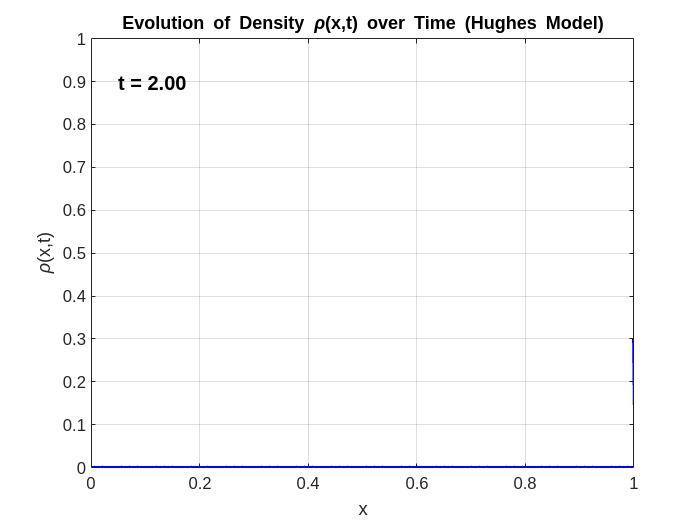

% ===================== Animation =====================
figure;
h = plot(X_hughes, rho_history(:, 1), 'LineWidth', 2, 'Color', 'b');
xlabel('x');
ylabel('\rho(x,t)');
title('Evolution of Density \rho(x,t) over Time (Hughes Model)');
grid on;
ylim([0 1]);   % Adjust according to your density range (0 to 1)
xlim([0 L_hughes]);
hold on;

xlim([0,L_hughes]);
ylim([0,1]);  % Maximum Density is 1


% Create a time annotation text
time_text = text(0.05, 0.9, sprintf('t = %.2f', 0), 'Units', 'normalized', ...
    'FontSize', 12, 'FontWeight', 'bold');
% Play animation
for t = 1:10:Time_Steps   % adjust step size for speed (e.g., 1:5:Time_Steps for smoother motion)
    set(h, 'YData', rho_history(:, t));      % update the line
    set(time_text, 'String', sprintf('t = %.2f', t * dt_hughes));  % update time label
    drawnow;                                 % refresh the plot
end

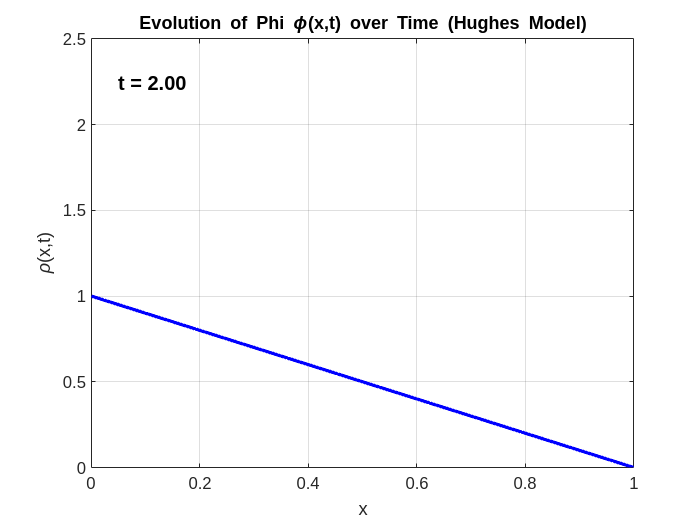

% ===================== Animation =====================
figure;
h = plot(X_hughes, phi_history(:, 1), 'LineWidth', 2, 'Color', 'b');
xlabel('x');
ylabel('\rho(x,t)');
title('Evolution of Phi \phi(x,t) over Time (Hughes Model)');
grid on;
hold on;

xlim([0,L_hughes]);
ylim([0,2.5]);  % from observation phi doesnt go above atmost 2.5

% Create a time annotation text
time_text = text(0.05, 0.9, sprintf('t = %.2f', 0), 'Units', 'normalized', ...
    'FontSize', 12, 'FontWeight', 'bold');

% Play animation
for t = 1:10:Time_Steps   % adjust step size for speed (e.g., 1:5:Time_Steps for smoother motion)
    set(h, 'YData', phi_history(:, t));      % update the line
    set(time_text, 'String', sprintf('t = %.2f', t * dt_hughes));  % update time label
    drawnow;                                 % refresh the plot
end

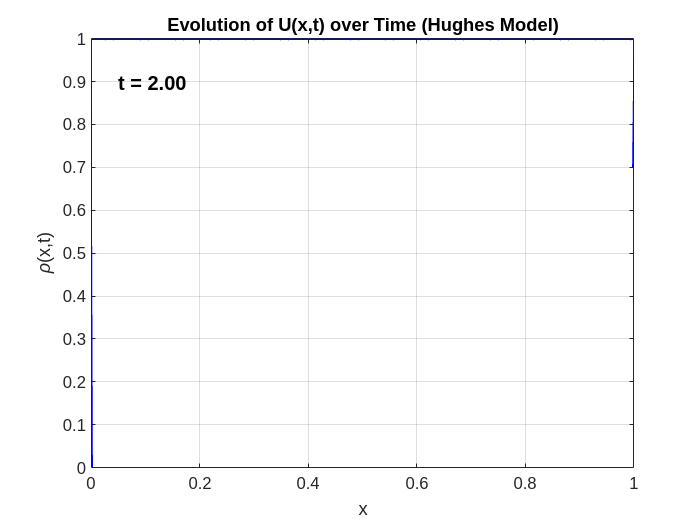

% ===================== Animation =====================
figure;
h = plot(X_hughes, U_history(:, 1), 'LineWidth', 2, 'Color', 'b');
xlabel('x');
ylabel('\rho(x,t)');
title('Evolution of U(x,t) over Time (Hughes Model)');
grid on;
hold on;

xlim([0,L_hughes]);
ylim([0,1]); % velocity has to be between 0 and 1, since 1 is the maximum velocity

% Create a time annotation text
time_text = text(0.05, 0.9, sprintf('t = %.2f', 0), 'Units', 'normalized', ...
    'FontSize', 12, 'FontWeight', 'bold');

% Play animation
for t = 1:10:Time_Steps   % adjust step size for speed (e.g., 1:5:Time_Steps for smoother motion)
    set(h, 'YData', U_history(:, t));      % update the line
    set(time_text, 'String', sprintf('t = %.2f', t * dt_hughes));  % update time label
    drawnow;                                 % refresh the plot
end